% --- Valeur par defaut pour que le simulink tourne
Kp = 0;
Ki = 0;
Kb = 0;
Kd = 0;

% -- Global parameters
p0 = [-5; -191.2; 93.5]; % Mesure initiale quand les moteurs sont à 0
dt = 1/ 30;

% --- Si données depuis simulink
data = out.logsout;
% --- Si préenregistré
%load("transfert_function.mat") 

% --- Recuperation des données
u = squeeze(getElement(data, "u").Values.Data);
z = squeeze(getElement(data, "z").Values.Data);

t  = getElement(data, "u").Values.Time;

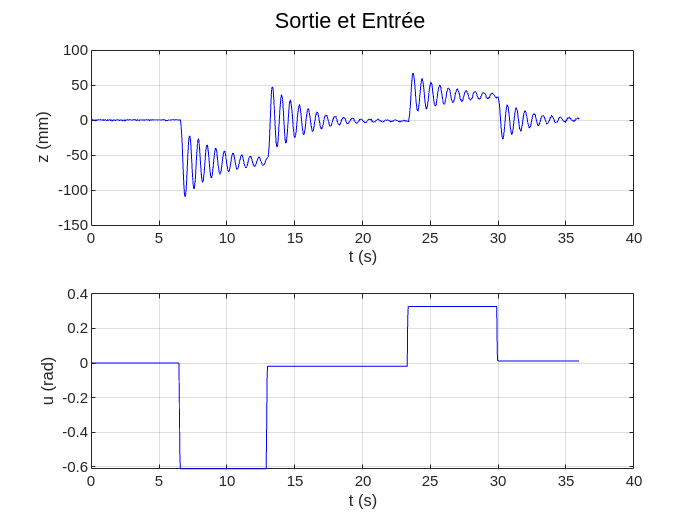

% --- Plot
figure;
subplot(2, 1, 1);
plot(t, z, 'b');
ylabel('z (mm)');
xlabel('t (s)');
grid on;

subplot(2, 1, 2);
plot(t, u, 'b');
ylabel('u (rad)');
xlabel('t (s)');
grid on;

sgtitle('Sortie et Entrée');

u_data = u - u(1);
z_data = z - z(1);

data_id = iddata(z_data, u_data, [], 'SamplingInstants', t);
sys = tfest(data_id, 2)


sys =
 
  From input "u1" to output "y1":
     -620.4 s + 9101
  ---------------------
  s^2 + 1.093 s + 91.77
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "data_id".
Fit to estimation data: 88.12%                      
FPE: 14.27, MSE: 14.12                              
 
Model Properties


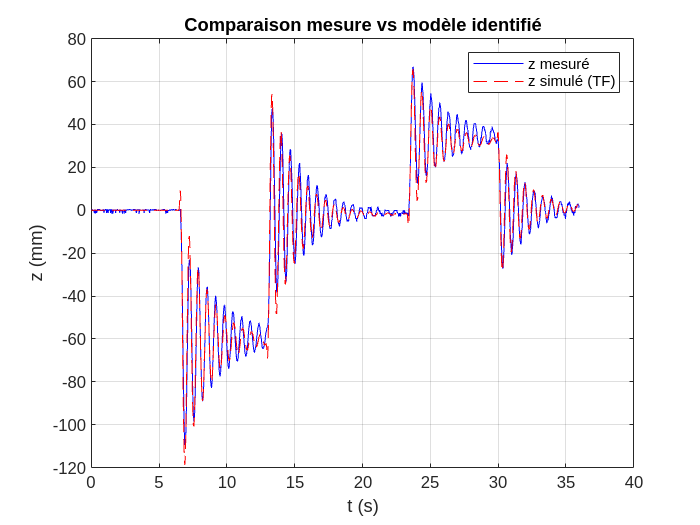

% --- Validation
% Simule la réponse de la TF identifiée avec ton vrai u comme entrée
z_sim = lsim(sys, u_data', t);

% Compare
figure;
plot(t, z_data', 'b', 'DisplayName', 'z mesuré');
hold on;
plot(t, z_sim, 'r--', 'DisplayName', 'z simulé (TF)');
ylabel('z (mm)');
xlabel('t (s)');
legend;
grid on;
title('Comparaison mesure vs modèle identifié');

% --- PID Tuning
sisotool(tf(sys))

% --- PID Tuning from State Space
sys_ss = ss(tf(sys));
A = sys_ss.A;
B = sys_ss.B;
C = sys_ss.C;
D = sys_ss.D;

% Transformation : on cherche T tel que C*T^-1 = [1 0]
% On construit T à partir de C et C*A (matrice d'observabilité)
Obs = obsv(A, C);   % [C ; C*A]
T = inv(Obs);       % changement de base

A_obs = Obs * A * T;
B_obs = Obs * B;
C_obs = C * T;       % doit donner [1 0]
D_obs = D;

damp(tf(sys))

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.46e-01 + 9.56e+00i     5.70e-02       9.58e+00         1.83e+00    
 -5.46e-01 - 9.56e+00i     5.70e-02       9.58e+00         1.83e+00    


Abar = [A_obs zeros(size(A_obs,1), 1); -C_obs 0];
Bbar = [B_obs; 0];

wn = 9.58;
xi = 0.3;

vpbar = [-xi*wn+j * wn * sqrt(1 - xi^2) -xi*wn-j*wn*sqrt(1 - xi^2) -1];

Kbar = place(Abar, Bbar, vpbar)

Kbar =    -0.0016    0.0005   -0.0101


Kp = Kbar(:, 1);
Kd = Kbar(: , 2);
Ki = -Kbar(:, 3);
Kb = 100;